# VARX Model 

## Setup

### Set paths

The VARX package is already included in this folder and will be added here:

addpath('../src/varx/matlab')

The up-to-date package is on github: [https://github.com/lcparra/varx](https://github.com/lcparra/varx) 

## Simple demo of VARX function 

This first example shows the basic usage of the varx() function on union participation and strike data in the US. 

### Background

Causal models are often employed in sociology. This example is motivated by work that has challenged the assumption that union membership provides resources for collective actions causing an increase the number of workers on strike. Alternatively, strikes could motivate more workers to join unions leading to an incrase in membership and thus provide benefits to unions even if demands to employers are not met (Hodder et al., 2016). Unemployment rate is included as an external variable. It is assumed that unemployment rate is not affected by union membership or number of workers on strike, but can influence either of these two variables. 

### Example

We will apply the VARX model on historical data of union membership, number of workers on strike and unemployment rate in the US. A more comprehensive discussion of this example is provided in Parra et al., 2025. 

First load and plot the data:

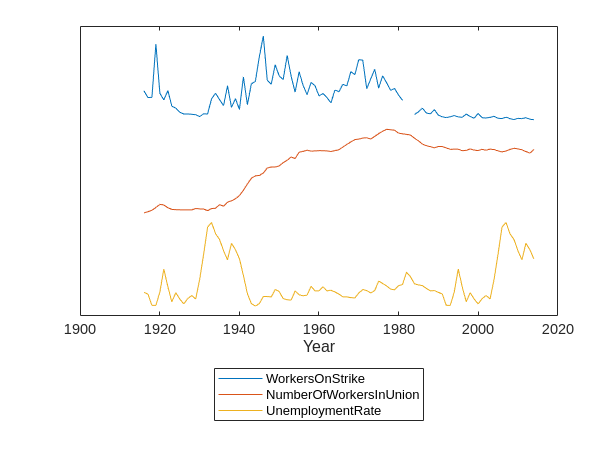

% Load the sample data
load('../data/union_data.mat', 'Y', 'X', 'Y_names', 'X_name', 'year')

% Plot the data over time 
plot(year, [Y, X])
stackplot
legend([Y_names, X_name],'Location','southoutside')
xlabel('Year')

Now we can compute the VARX model. We consider 'WorkersOnStrike' and 'NumberOfWorkersInUnion' as 'output' of the system y(t). They are also refered to as endogenous variables as they influcence each other. Later, in the context of neural data we will call these intrinsic variables. 'UnemploymentRate' is the 'input' to the system x(t). By definition the input is not affected by the output and by other input variables. For analysis of neural data we will also refer to inputs as extrinstic variables. 

% First set the parameters 
na = 3;         % Number of years for the potential effect of instrinsic effects on each other
nb = 3;         % Number of years to consider for external effects
lambda = 0;     % The regularization parameter lambda can control for overfitting

% Compute the VARX model
model = varx(Y,na,X,nb,lambda);

Let's examine the model! 

The VARX model estimates the effect B of the input variable 'UnemploymentRate' on each of the two endogenous variables. The filter B is of size nb x dy, where dy is the number of endogenous variables ('WorkersOnStrike' and 'NumberOfWorkersInUnion'). 

fprintf('Size of B: %d x %d\n', size(model.B))

Size of B: 3 x 2


The internal state of the system is modelled by the filter matrix A, which captures the effects of each intrinsic variable on each of the others. A is of size na x dy x dy. 

fprintf('Size of A: %d x %d x %d\n', size(model.A))

Size of A: 3 x 2 x 2


The computation of A and B filters comprises the system identification. The Granger formalism establishes whether the effect of any channel (extrinsic or intrinsic) on another is significant. This is achieved by comparing the full model to a model with one predictor removed (reduced model). The deviance and effect size R capture the magnitude of this effect, the p-value estimates the statistical significance.  

The model estimates the effect size R for the input variable on each endogenous variable:

fprintf('Size of B R-values: %d x %d\n', size(model.B_Rvalue))

Size of B R-values: 2 x 1


And between each endogenous variable:

fprintf('Size of A R-values: %d x %d\n', size(model.A_Rvalue))

Size of A R-values: 2 x 2


Looking at the effect of unemployment rate we see that it has a significant effect on the number of workers in unions, but not the number of workers on strike:

for i = 1:size(model.B_Rvalue,1)
    fprintf('%s -> %s: R = %1.3f, p = %1.3f\n', X_name{1}, Y_names{i}, model.B_Rvalue(i,1), model.B_pval(i,1))
end

UnemploymentRate -> WorkersOnStrike: R = 0.098, p = 0.829
UnemploymentRate -> NumberOfWorkersInUnion: R = 0.301, p = 0.035


Next, the model shows us the effects of the number of workers on strike and number of workers in unions on each other. The columns in the A matrix are the independent variables, i.e. the cause y(t-1); rows are the dependent variables, i.e. the effect on y(t). Diagonals are the autoregressive effects of variables on themselves. In the example, we see that the effect size of 'WorkersOnStrike' on 'NumberOfWorkersInUnion' (first column on second row), is larger than the effect of 'NumberOfWorkersInUnion' on 'WorkersOnStrike' (second column on first row). This is determined by the order of the variables in the array Y. 

for i = 1:size(model.A_Rvalue,2)
    for j = 1:size(model.A_Rvalue,1)
        if i~=j
            fprintf('%s -> %s: R = %1.3f, p = %1.3f\n', ...
                Y_names{i}, Y_names{j}, model.A_Rvalue(j,i), model.A_pval(j,i))
        end
    end
end

WorkersOnStrike -> NumberOfWorkersInUnion: R = 0.345, p = 0.009
NumberOfWorkersInUnion -> WorkersOnStrike: R = 0.294, p = 0.042


This model therefore supports the claim by Hodder et al., that strikes increase union membership. 

## Analysis of neural data

With some intuition of the VARX model we can delve into neural data. We will demonstrate the effects of the VARX model in comparison to mTRF on the data of one of the patients in Nentwich et al., 2025. The patient watched audiovisual movies during continuous recordings of intracranial EEG and eyetracking. 

### Setup

Download the data from OSF and define the path to the data directory:

data_dir = '/media/max/Workspace/Data/varx_tutorial_data';

**Load data**

% List all files
data_files = dir(sprintf('%s/recordings', data_dir));

% Remove directories
data_files([data_files.isdir]) = [];

In the first analysis all movies are concatenated. 

Not all movies have the same features. The 'Monkey' movies are silent. However, to get comparable filters when comparing movies, sound from other movies has been copied. 

% Select only movies (exclude 5 minute long copy and resting state)
idx_movies = cellfun(@(C) ~contains(C, {'Despicable_Me_English_5min', 'Resting_fixation'}), {data_files.name});
movie_files = data_files(idx_movies);

% Load all files 
X = cell(length(movie_files), 1);
X_shift = cell(length(movie_files), 1);
Y = cell(length(movie_files), 1);

for f = 1:length(movie_files)

    % For inscapes zeros are used for film cuts (the movie does not have cuts)
    if strcmp(movie_files(f).name, 'Inscapes.mat')

        load(sprintf('%s/recordings/%s', data_dir, movie_files(f).name), ...
            'lfp', 'hfa', 'fs', ...
            'fixations', 'fixation_novelty', 'audio_env', 'edge_vec')
    
        film_cuts = zeros(1, length(fixations));

    else

        load(sprintf('%s/recordings/%s', data_dir, movie_files(f).name), ...
            'lfp', 'hfa', 'fs', ...
            'fixations', 'fixation_novelty', 'audio_env', 'edge_vec', 'film_cuts')
    
    end

    X{f} = [fixations, fixation_novelty, audio_env', edge_vec, film_cuts'];
    Y{f} = lfp;

    % Shift input vector
    n_shift = round(length(X{f})/2);
    X_shift{f} = [X{f}(n_shift:end, :); X{f}(1:n_shift-1, :)];

end

% Name the input channels
x_names = {'Fixations', 'Fixation Novelty', 'Sound Envelope', 'Acoustic Edges', 'Film Cuts'};

% Load the channel labels and regeion of interest labels
load(sprintf('%s/channel_roi.mat', data_dir), 'roi')
load(sprintf('%s/channel_labels.mat', data_dir), 'labels')

### Compute the model

% Model parameters
ta = 0.1;       % length of the VARX autoregressive filters A in seconds
tb = 0.6;       % length of the VARX input filter B in seconds
gamma = 0.3;    % Regularization parameter

% Compute filter length in samples
na = ta*fs;
nb = tb*fs;

% Compute the model
model_varx = varx(Y,na,X,nb,lambda);


### Visualize the input and recurrent filters

#### Input filters

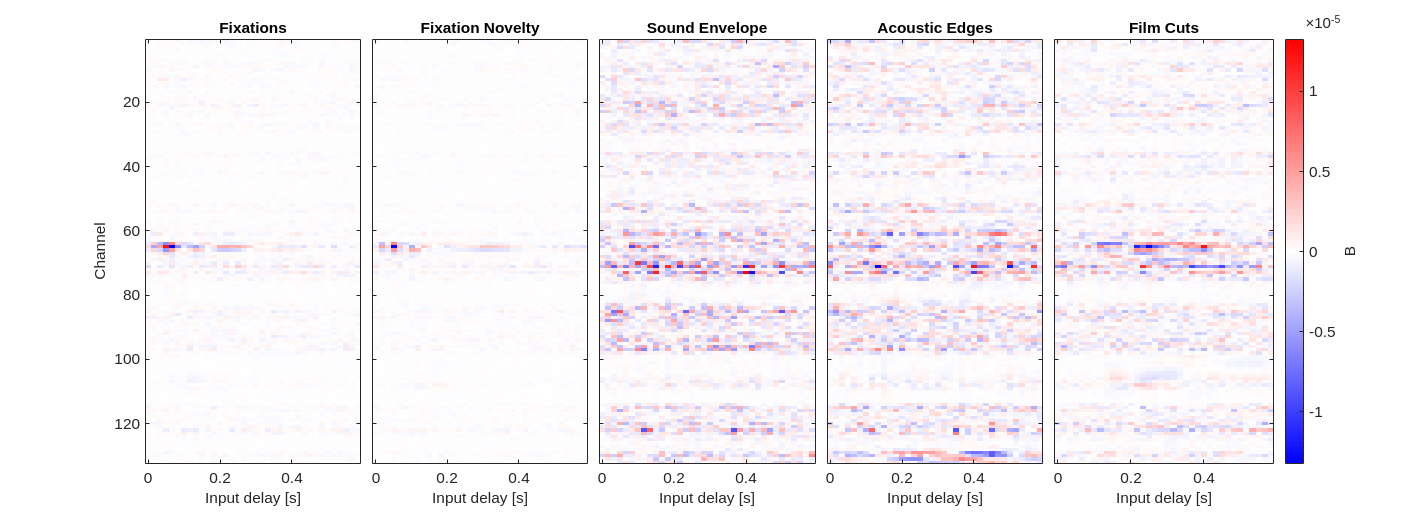

% Get the time vector
t = (0:nb-1) / fs;

% Number of input features
dx = size(model_varx.B,3); 

% Load custom colormap 
% From:
% Zhaoxu Liu / slandarer (2025). 200 colormap (https://www.mathworks.com/matlabcentral/fileexchange/120088-200-colormap), 
% MATLAB Central File Exchange. Retrieved August 15, 2025.
load('../src/cutsom_colormaps.mat', 'colormap_reds', 'colormap_bwr')

% Plot all input responses
figure('Position', [0,0,1350,500])

space = 50;
tiledlayout(1,space*dx+1)

for b = 1:dx
    plt_max = max(max(abs(model_varx.B(:,:,b))));

    if b ~= dx, nexttile([1,space]), else, nexttile([1,space+1]), end

    imagesc([t(1), t(end)], [1, size(model_varx.B,2)], model_varx.B(:,:,b)')
    caxis([-plt_max, plt_max])
    colormap(colormap_bwr)
    title(x_names{b})
    if b ~= 1, yticklabels([]), else, ylabel('Channel'), end
    if b == dx, c = colorbar; c.Label.String = 'B'; end
    xlabel('Input delay [s]')

end

fontsize(14, 'pixels') 

The responses are mostly limited to a small number of channels. Below are plots of the input filters in channels with the largest effect size. 

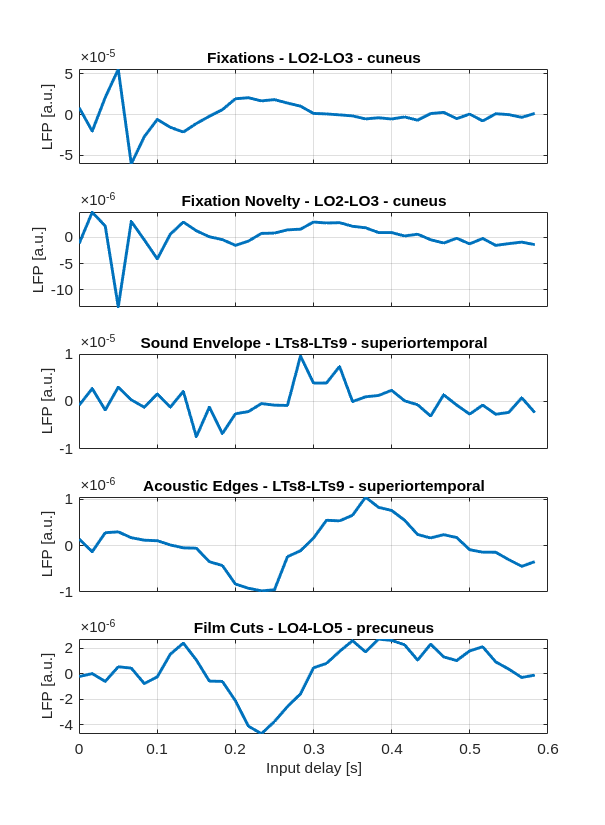

% Select the channels with the largest R value
[~, idx_max_B] = max(model_varx.B_Rvalue);

% Plot the input filters
figure('Position', [0,0,550,750])

for b = 1:dx
    subplot(dx,1,b)
    plot(t,model_varx.B(:,idx_max_B(b),b), 'LineWidth', 2)
    title(sprintf('%s - %s - %s', x_names{b}, labels{idx_max_B(b)}, roi{idx_max_B(b), 1}))
    if b ~= dx, xticklabels([]), else, xlabel('Input delay [s]'), end
    ylabel('LFP [a.u.]')
    grid on
end
fontsize(14, 'pixels') 

#### Recurret dynamics

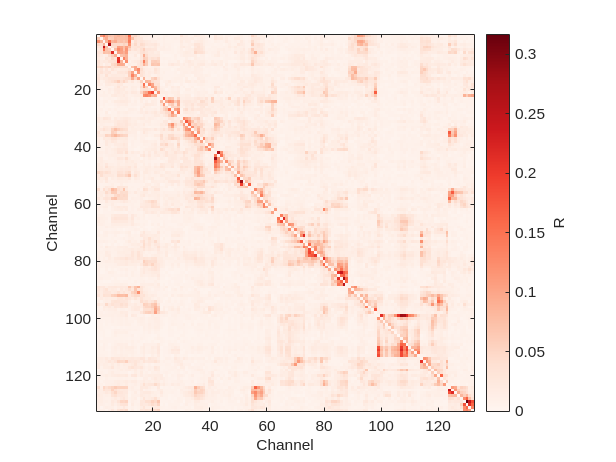

% Process the data a bit for nicer plots
% The largest R values are on the diagonal, but those are not intersting 
AR = model_varx.A_Rvalue;
AR(eye(size(AR))==1) = 0;

figure()
imagesc(AR)
colormap(colormap_reds)
c = colorbar;
c.Label.String = 'R';
xlabel('Channel')
ylabel('Channel')
axis square
title('VARX Recurrent connections')
fontsize(14, 'pixels') 

### Compare to the model without inputs

A VAR model without inputs has a different number of parameters so it is harder to compare. We shifted the input to get models comparable models with unaligned input, but perserving the model structure. 

model_var = varx(Y,na,X_shift,nb,lambda);
% The varx function can also be called without input, but to compare the
% two models it is better to preserve the statistics of the input
% model_var = varx(Y,na,[],0,lambda);

#### Plot the difference to the full VARX model with inputs

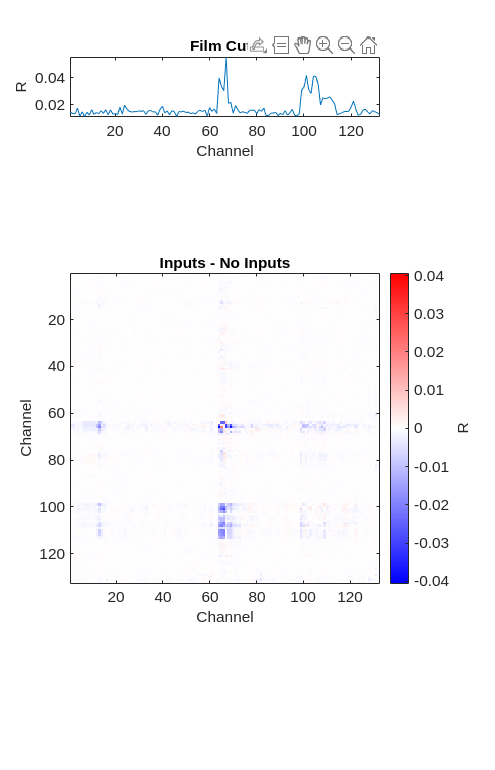

% Remove diagonal from VAR model
AR_var = model_var.A_Rvalue;
AR_var(eye(size(AR_var))==1) = 0;

% Difference
AR_diff = AR-AR_var;

% Find range to center coloraxis around zero
AR_diff_max = max(abs(AR_diff(:)));

% Figure
figure('Position', [0,0,450,700])
tiledlayout(6,1)

% Plot the R values for Film cuts (index 5)
nexttile
plot(model_varx.B_Rvalue(:,5))
if b ~= dx, xticklabels([]), else, xlabel('Channel'), end
ylabel('R')
xlim([1,size(model_varx.B_Rvalue,1)])
title(x_names{5})

nexttile([5,1])

% Plot the difference in R values for the A matrices
imagesc(AR_diff)
caxis([-AR_diff_max, AR_diff_max])
colormap(colormap_bwr)
c = colorbar;
c.Label.String = 'R';
xlabel('Channel')
ylabel('Channel')
axis square
title('Inputs - No Inputs')
fontsize(14, 'pixels')

The blue channel pairs show a decrease in effect size when external inputs are included in the model. Two different clusters of channels show responses to visual inputs, such as film cuts (64-69 in the cuneus and 99-113 in the lateraloccipital cortex). If visual inputs are not included in the model these two clusters would show a strong spurious connection to each other. 

### Input filters B versus TRFs

## Note on parameter selection

An option is to use the AIC or BIC criterions (REFs). AIC for linear regerssion can be computed following (https://stats.stackexchange.com/questions/261273/how-can-i-apply-akaike-information-criterion-and-calculate-it-for-linear-regress). 

Example in matlab implementation: [https://www.mathworks.com/help/econ/var-model-estimation.html](https://www.mathworks.com/help/econ/var-model-estimation.html) 

% nas = 1:4:20;
% AIC = zeros(1,length(nas));
% 
% for i = 1:length(nas)
%     model_na = varx(Y,nas(i),X,nb,lambda);
%     AIC(i) = mean(model_na.T * log(model_na.s2)) + 2*(nas(i)+nb);
% end
% figure
% plot(nas, AIC)

## References

Hodder, Andy, et al. "Does strike action stimulate trade union membership growth?." *British Journal of Industrial Relations* 55.1 (2017): 165-186.

Parra, Lucas C., et al. "VARX Granger analysis: Models for neuroscience, physiology, sociology and econometrics." *PloS one* 20.1 (2025): e0313875.

Nentwich, Maximilian, et al. "Intrinsic dynamic shapes responses to external stimulation in the human brain." *eLife* 14 (2025): RP104996.